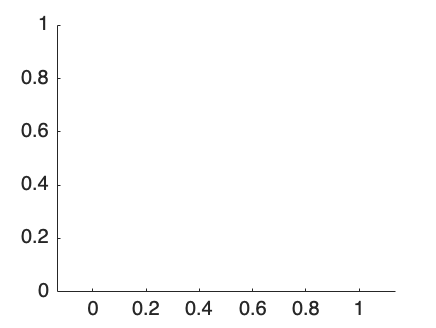

Index in position 2 exceeds array bounds. Index must not exceed 1.

tessellation = tessellation_compacted;
figure(1)
for a = 0:0.02:1
    cla
    for i = 1:3
        for j = 1:3
%             d1 = tessellation_compacted{i,j}(4,:) -tessellation{i,j}(4,:); 
%             d2 = tessellation_compacted{i,j}(13,:) - tessellation{i,j}(13,:);
%             angle1 = angle_calculate([tessellation_optimized{i,j}(1,:)+d1;tessellation_optimized{i,j}(4,:)+d1;tessellation_compacted{i,j}(1,:)]);
%             angle2 = angle_calculate([tessellation_optimized{i,j}(6,:)+d1;tessellation_optimized{i,j}(7,:)+d1;tessellation_compacted{i,j}(6,:)]);
%             angle3 = angle_calculate([tessellation_optimized{i,j}(11,:)+d2;tessellation_optimized{i,j}(10,:)+d2;tessellation_compacted{i,j}(11,:)]);
%             angle4 = angle_calculate([tessellation_optimized{i,j}(16,:)+d2;tessellation_optimized{i,j}(13,:)+d2;tessellation_compacted{i,j}(16,:)]);
            angle_e1 = angle_calculate([tessellation_optimized{i,j}([4,13,6],:)]);
            angle_e2 = angle_calculate([tessellation_optimized{i,j}([1,4,13],:)]);
            angle_r = angle_calculate([tessellation_optimized{i,j}([4,13],:);[1e9,0]]);
            l = length_calculate(tessellation_optimized{i,j}([1,4],:));
            d = l*cos(angle_r)*2;
            square_transformed1 = transform_square(tessellation{i,j}(1:4,:),angle_r,[0 0],tessellation{i,j}(8,:));
            square_transformed1 = transform_square(square_transformed1,-angle_e2,[0 0],square_transformed1(4,:));
            square_transformed2 = transform_square(tessellation{i,j}(5:8,:),angle_r,[0 0],tessellation{i,j}(8,:));
            square_transformed2 = transform_square(square_transformed2,angle_e2,[0 0],square_transformed2(3,:));
            square_transformed3 = transform_square(tessellation{i,j}(9:12,:),angle_r,[0 0],tessellation{i,j}(8,:));
            square_transformed3 = transform_square(square_transformed3,-angle_e1,[0 0],square_transformed3(2,:));
            square_transformed4 = transform_square(tessellation{i,j}(13:16,:),angle_r,[0 0],tessellation{i,j}(8,:));
            square_transformed4 = transform_square(square_transformed4,angle_e1,[0 0],square_transformed4(1,:));
            g = length_calculate([square_transformed1(4,:);square_transformed4(1,:)]);
            t = (g-d)/2;
            %square_transformed1 = transform_square(square_transformed1,0,[-t*cos(angle_r) -t*sin(angle_r)],square_transformed1(4,:));
            %square_transformed2 = transform_square(square_transformed2,0,[-t*cos(angle_r) -t*sin(angle_r)],square_transformed2(3,:));
            %square_transformed3 = transform_square(square_transformed3,0,[t*cos(angle_r) t*sin(angle_r)],square_transformed3(2,:));
            %square_transformed4 = transform_square(square_transformed4,0,[t*cos(angle_r) t*sin(angle_r)],square_transformed4(1,:));
%             square_transformed1 = transform_square(tessellation{i,j}(1:4,:),angle1*a,a*d1,tessellation{i,j}(4,:));
%             square_transformed2 = transform_square(tessellation{i,j}(5:8,:),-angle2*a,a*d1,tessellation{i,j}(7,:));
%             square_transformed3 = transform_square(tessellation{i,j}(9:12,:),angle3*a,a*d2,tessellation{i,j}(10,:));
%             square_transformed4 = transform_square(tessellation{i,j}(13:16,:),-angle4*a,a*d2,tessellation{i,j}(13,:));
            tessellation_transformed{i,j} = [square_transformed1([1:4],:);
                square_transformed2([1:4],:);
                square_transformed3([1:4],:);
                square_transformed4([1:4],:)];
            %transform_square(tessellation{1,1}(1,:),angle1,d1,tessellation{1,1}(4,:))
            %=
            %transform_square(tessellation{1,1}(16,:),-angle4,d2,tessellation{1,1}(13,:));
            %transform_square(tessellation{1,1}(6,:),-angle2,d1,tessellation{1,1}(7,:))
            %=
            %transform_square(tessellation{1,1}(11,:),angle3,d2,tessellation{1,1}(10,:));
        end
    end
    tessellation = cell(1,1);
    tessellation{1,1} = tessellation_transformed{1,1};
    plot_tessellation(tessellation);
    drawnow
end